I = imread('C:/dev/biomedeng/Associated Files/Chapter 15/mri.tif')

I = 128×128 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

I = im2double(I)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

fft = fft2(I)% Take 2D FFT

fft = 1.0e+03 *

   1.4355 + 0.0000i  -0.8363 - 0.0278i  -0.0363 + 0.0071i   0.1413 + 0.0055i   0.0823 + 0.0120i  -0.0521 - 0.0070i  -0.0220 - 0.0142i  -0.0316 + 0.0078i   0.0501 + 0.0044i   0.0070 + 0.0071i  -0.0324 - 0.0120i   0.0061 - 0.0031i   0.0006 + 0.0015i   0.0179 + 0.0120i   0.0016 + 0.0003i  -0.0332 - 0.0156i   0.0168 + 0.0040i   0.0047 + 0.0037i   0.0030 + 0.0039i  -0.0072 - 0.0019i   0.0117 - 0.0016i  -0.0233 - 0.0033i   0.0153 + 0.0010i  -0.0047 + 0.0029i   0.0132 + 0.0023i  -0.0118 - 0.0035i  -0.0035 - 0.0021i   0.0040 + 0.0037i   0.0008 - 0.0044i   0.0030 + 0.0076i   0.0022 - 0.0047i  -0.0110 - 0.0026i   0.0019 + 0.0018i   0.0067 + 0.0032i   0.0005 - 0.0002i  -0.0024 - 0.0029i  -0.0017 - 0.0018i  -0.0029 + 0.0031i   0.0057 + 0.0005i  -0.0030 - 0.0000i   0.0039 - 0.0010i  -0.0010 + 0.0007i  -0.0045 - 0.0028i   0.0010 + 0.0037i   0.0007 - 0.0028i   0.0042 + 0.0038i  -0.0020 - 0.0041i  -0.0024 + 0.0033i  -0.0011 - 0.0048i   0.0042 + 0.0067i
  -0.6154 + 0.2118i   0.2641 - 0

fft_p = fftshift(abs(fft))% Shift and abs

fft_p = 1.0e+03 *

    0.0033    0.0023    0.0022    0.0032    0.0038    0.0013    0.0023    0.0043    0.0035    0.0012    0.0008    0.0025    0.0036    0.0021    0.0050    0.0051    0.0027    0.0039    0.0040    0.0013    0.0012    0.0014    0.0028    0.0048    0.0038    0.0004    0.0010    0.0008    0.0011    0.0010    0.0025    0.0018    0.0015    0.0012    0.0024    0.0013    0.0033    0.0037    0.0008    0.0019    0.0022    0.0012    0.0007    0.0024    0.0039    0.0036    0.0035    0.0028    0.0019    0.0049
    0.0024    0.0028    0.0027    0.0030    0.0036    0.0028    0.0006    0.0018    0.0020    0.0015    0.0014    0.0005    0.0019    0.0020    0.0042    0.0046    0.0011    0.0041    0.0033    0.0020    0.0014    0.0022    0.0030    0.0016    0.0030    0.0028    0.0024    0.0021    0.0019    0.0035    0.0043    0.0033    0.0051    0.0050    0.0031    0.0021    0.0040    0.0034    0.0031    0.0046    0.0019    0.0024    0.0026    0.0024    0.0008    0.0012    0.0047    0.0056


fft_2 = fft%Modified fft

fft_2 = 1.0e+03 *

   1.4355 + 0.0000i  -0.8363 - 0.0278i  -0.0363 + 0.0071i   0.1413 + 0.0055i   0.0823 + 0.0120i  -0.0521 - 0.0070i  -0.0220 - 0.0142i  -0.0316 + 0.0078i   0.0501 + 0.0044i   0.0070 + 0.0071i  -0.0324 - 0.0120i   0.0061 - 0.0031i   0.0006 + 0.0015i   0.0179 + 0.0120i   0.0016 + 0.0003i  -0.0332 - 0.0156i   0.0168 + 0.0040i   0.0047 + 0.0037i   0.0030 + 0.0039i  -0.0072 - 0.0019i   0.0117 - 0.0016i  -0.0233 - 0.0033i   0.0153 + 0.0010i  -0.0047 + 0.0029i   0.0132 + 0.0023i  -0.0118 - 0.0035i  -0.0035 - 0.0021i   0.0040 + 0.0037i   0.0008 - 0.0044i   0.0030 + 0.0076i   0.0022 - 0.0047i  -0.0110 - 0.0026i   0.0019 + 0.0018i   0.0067 + 0.0032i   0.0005 - 0.0002i  -0.0024 - 0.0029i  -0.0017 - 0.0018i  -0.0029 + 0.0031i   0.0057 + 0.0005i  -0.0030 - 0.0000i   0.0039 - 0.0010i  -0.0010 + 0.0007i  -0.0045 - 0.0028i   0.0010 + 0.0037i   0.0007 - 0.0028i   0.0042 + 0.0038i  -0.0020 - 0.0041i  -0.0024 + 0.0033i  -0.0011 - 0.0048i   0.0042 + 0.0067i
  -0.6154 + 0.2118i   0.2641 -

fft_2(2:2:end) = 0 %Zero out every other row

fft_2 = 1.0e+03 *

   1.4355 + 0.0000i  -0.8363 - 0.0278i  -0.0363 + 0.0071i   0.1413 + 0.0055i   0.0823 + 0.0120i  -0.0521 - 0.0070i  -0.0220 - 0.0142i  -0.0316 + 0.0078i   0.0501 + 0.0044i   0.0070 + 0.0071i  -0.0324 - 0.0120i   0.0061 - 0.0031i   0.0006 + 0.0015i   0.0179 + 0.0120i   0.0016 + 0.0003i  -0.0332 - 0.0156i   0.0168 + 0.0040i   0.0047 + 0.0037i   0.0030 + 0.0039i  -0.0072 - 0.0019i   0.0117 - 0.0016i  -0.0233 - 0.0033i   0.0153 + 0.0010i  -0.0047 + 0.0029i   0.0132 + 0.0023i  -0.0118 - 0.0035i  -0.0035 - 0.0021i   0.0040 + 0.0037i   0.0008 - 0.0044i   0.0030 + 0.0076i   0.0022 - 0.0047i  -0.0110 - 0.0026i   0.0019 + 0.0018i   0.0067 + 0.0032i   0.0005 - 0.0002i  -0.0024 - 0.0029i  -0.0017 - 0.0018i  -0.0029 + 0.0031i   0.0057 + 0.0005i  -0.0030 - 0.0000i   0.0039 - 0.0010i  -0.0010 + 0.0007i  -0.0045 - 0.0028i   0.0010 + 0.0037i   0.0007 - 0.0028i   0.0042 + 0.0038i  -0.0020 - 0.0041i  -0.0024 + 0.0033i  -0.0011 - 0.0048i   0.0042 + 0.0067i
   0.0000 + 0.0000i   0.0000 +

fft_p2 = fftshift(abs(fft_2))% Shift and abs

fft_p2 = 1.0e+03 *

    0.0033    0.0023    0.0022    0.0032    0.0038    0.0013    0.0023    0.0043    0.0035    0.0012    0.0008    0.0025    0.0036    0.0021    0.0050    0.0051    0.0027    0.0039    0.0040    0.0013    0.0012    0.0014    0.0028    0.0048    0.0038    0.0004    0.0010    0.0008    0.0011    0.0010    0.0025    0.0018    0.0015    0.0012    0.0024    0.0013    0.0033    0.0037    0.0008    0.0019    0.0022    0.0012    0.0007    0.0024    0.0039    0.0036    0.0035    0.0028    0.0019    0.0049
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         


I2 = ifft2(fft_2)%Inverse of the modified

I2 =     0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000         0   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000   -0.0000    0.1627    0.1725    0.1725    0.1725    0.1725    0.1725    0.1059    0.1059    0.0941    0.1137    0.1059    0.1608    0.1725    0.1725    0.0902    0.1020    0.1020    0.1255    0.1078    0.1412    0.1412    0.1725    0.1725    0.1725
   -0.0000    0.0000   -0.0000    0.0000    0.0000         0    0.0000    0.0000   -0.0000         0         0    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000         0   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0255    0.1725    0.1725    0.1725    0.1725    0.1725    0.1725    0.1392    0.1039    0.0961    0.1020    0.1000    0.1725    0.1725    0.1176    0.0882    0.0941    0.1059    0.1157    0.1157    0.1392    0.1431    0.1725    0.1725    

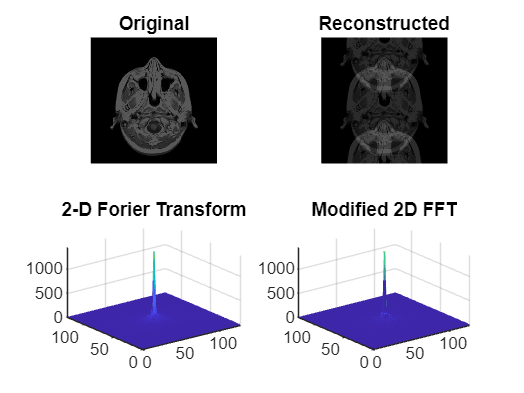


subplot(2, 2, 1)
imshow(I)
title('Original')

subplot(2,2,2)
imshow(I2)
title('Reconstructed')

subplot(2,2,3)
mesh(fft_p)
title('2-D Forier Transform')

subplot(2,2,4)
mesh(fft_p2)
title('Modified 2D FFT')